analyse the simulated data

first check the nascent data is sane

What does the ground truth look like

fDir = 'D:\z dynamics paper\nascent_zdynamic_sim\nascentDensity'

fDir = 'D:\z dynamics paper\nascent_zdynamic_sim\nascentDensity'

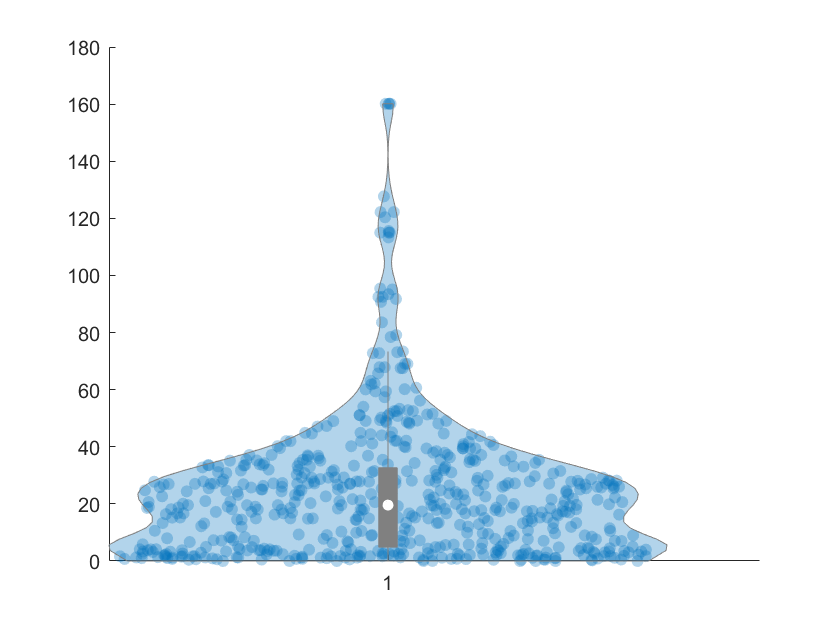

fname='simZRing_nAvg6_';
GT_stub='_GT.mat';
nFile=100;
trackTableGT =table;
%ii=1;
for ii =1:nFile
    ii;
    fCur= fullfile(fDir,[fname,sprintf('%03i', ii),GT_stub]);
    load(fCur,'groundTruth','simPar','nTrackAvg');
    trackTableGT=[trackTableGT;groundTruth.trackTable];
end

violinplot(trackTableGT.S);

size(trackTableGT,1)

ans = 600

analysed tracks

analysedFname=fullfile(fDir,'analysed/analysed_tracks_global.csv');
trackObs=readtable(analysedFname);

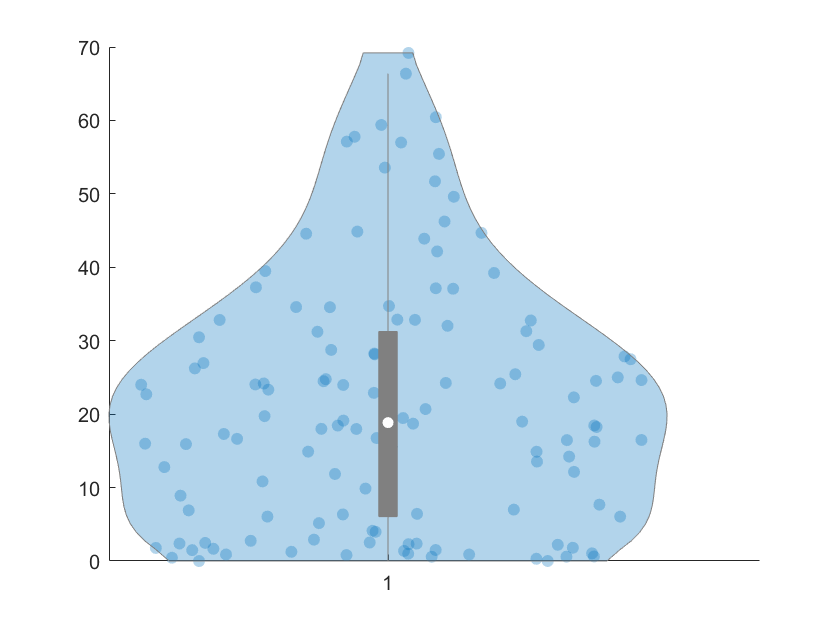

s=abs(trackObs.Speed_nm_s_);
figure;
violinplot(s);

looks approximately ok first pass

better check all tracks are really included in sim (sounds stupid)


ii=1;

fname=['simZRing_nAvg6_', sprintf('%03i', ii)]

fname = 'simZRing_nAvg6_001'

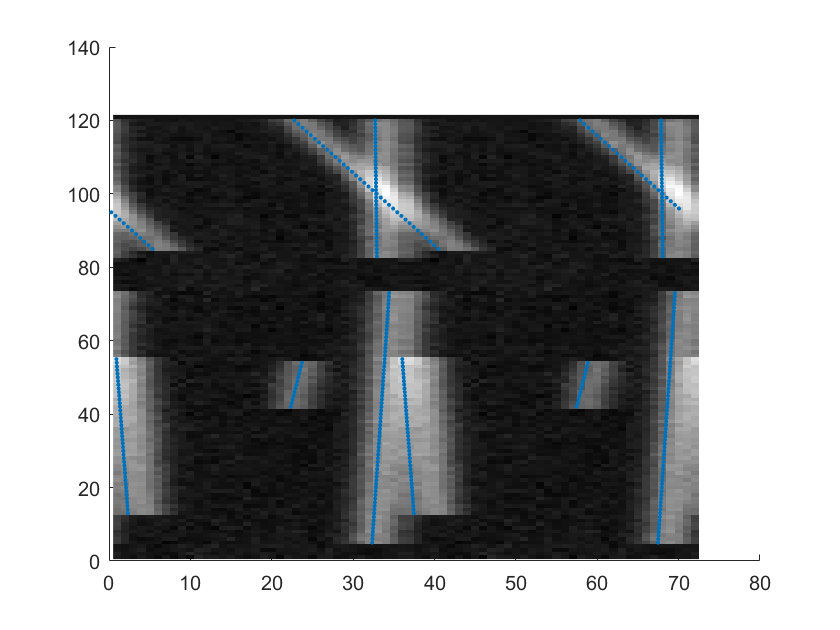

GT=load(fullfile(fDir,[fname,GT_stub]),'groundTruth');
GT=GT.groundTruth;
kymoIm = imread(fullfile(fDir,'analysed',[fname,'_denoise_kymoWrap.tif']));
f= load(fullfile(fDir,'analysed',[fname,'_denoise_fitData.mat']),'kymoInfo');
kymoInfo=f.kymoInfo;
diam=kymoInfo(1,2)*2;
theta=GT.trackCoord.theta;
fr=GT.trackCoord.fr;
%double up the angles
theta=[theta;theta+2*pi];
fr=repmat(fr,2,1);  
arcPix = theta*diam/(2*simPar.pixSizenm);
figure;
hold all;
imagesc(kymoIm);
colormap gray;
plot(arcPix,fr,'.')


s=[];
t=[]


t =

     []



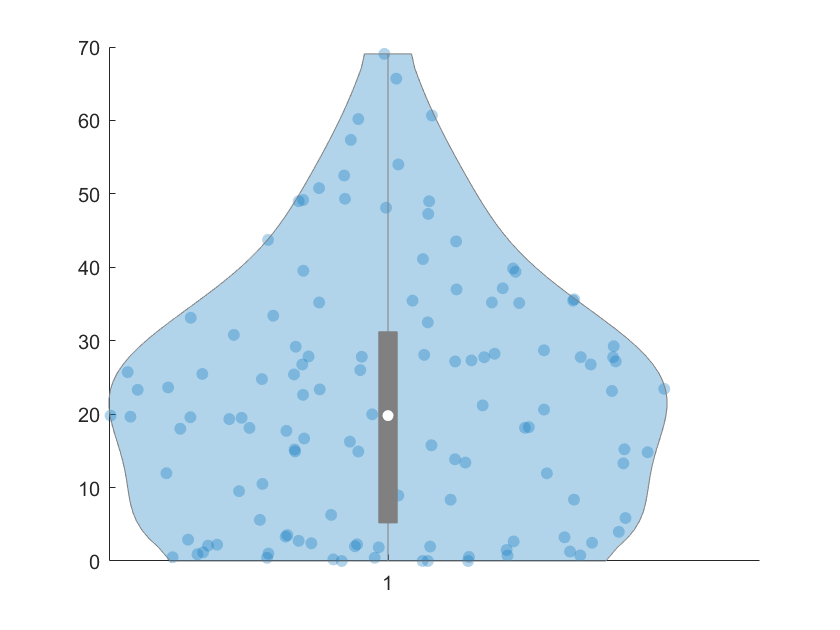

ans =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: [1×1 Patch]
        BoxPlot: [1×1 Patch]
    WhiskerPlot: [1×1 Line]
     MedianPlot: [1×1 Scatter]
     NotchPlots: [1×2 Scatter]
       MeanPlot: [1×1 Line]
    ViolinColor: [0 0.4470 0.7410]
    ViolinAlpha: 0.3000
      EdgeColor: [0.5000 0.5000 0.5000]
       BoxColor: [0.5000 0.5000 0.5000]
       BoxWidth: 0.0200
    MedianColor: [1 1 1]
       ShowData: 1
    ShowNotches: 0
       ShowMean: 0


fileNo=[];
ii=1;
for ii =1:20
    sFile=[];
    tFile=[];
    fname=['simZRing_nAvg6_', sprintf('%03i', ii)];
    GT=load(fullfile(fDir,[fname,GT_stub]),'groundTruth');
    GT=GT.groundTruth;
    trackNo=unique(GT.trackCoord.id);
    for jj=trackNo'
        thetaCur= GT.trackCoord.theta(GT.trackCoord.id==jj);
        if numel(thetaCur)>=2
            sCur=abs(min(mod(thetaCur(2)-thetaCur(1),2*pi),mod(thetaCur(1)-thetaCur(2),2*pi)))*880/2;
            sFile=[sFile;sCur];
            tFile=[tFile;thetaCur(1)];
        end
    end
    fileNo=[fileNo;ii*ones(size(sFile))];
    s=[s;sFile];
    t=[t;tFile];
end
gtResult=table(fileNo,s,t);

figure;
violinplot(gtResult.s)


s=[];
t=[]


t =

     []



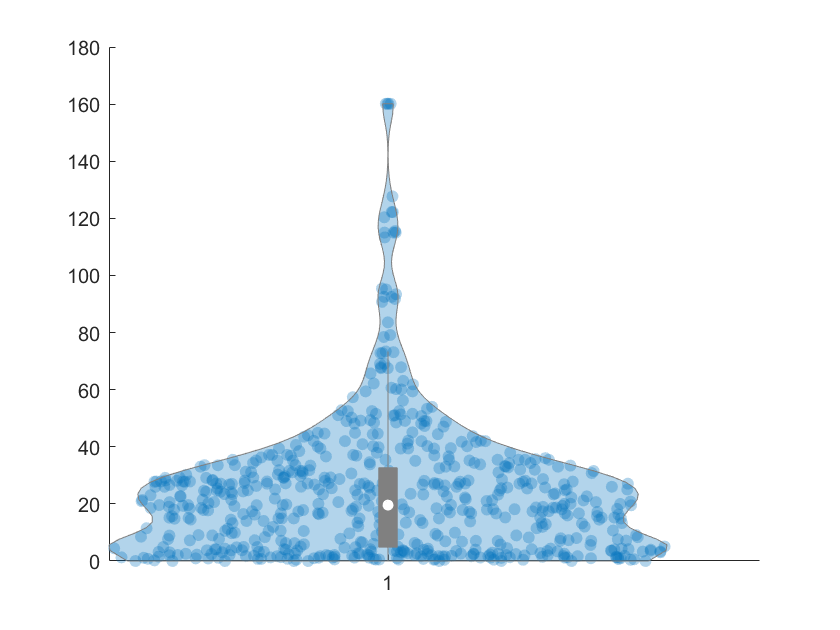

ans =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: [1×1 Patch]
        BoxPlot: [1×1 Patch]
    WhiskerPlot: [1×1 Line]
     MedianPlot: [1×1 Scatter]
     NotchPlots: [1×2 Scatter]
       MeanPlot: [1×1 Line]
    ViolinColor: [0 0.4470 0.7410]
    ViolinAlpha: 0.3000
      EdgeColor: [0.5000 0.5000 0.5000]
       BoxColor: [0.5000 0.5000 0.5000]
       BoxWidth: 0.0200
    MedianColor: [1 1 1]
       ShowData: 1
    ShowNotches: 0
       ShowMean: 0


fileNo=[];
ii=1;
for ii =1:100
    sFile=[];
    tFile=[];
    fname=['simZRing_nAvg6_', sprintf('%03i', ii)];
    GT=load(fullfile(fDir,[fname,GT_stub]),'groundTruth');
    GT=GT.groundTruth;
    trackNo=unique(GT.trackCoord.id);
    for jj=trackNo'
        thetaCur= GT.trackCoord.theta(GT.trackCoord.id==jj);
        if numel(thetaCur)>=2
            sCur=abs(min(mod(thetaCur(2)-thetaCur(1),2*pi),mod(thetaCur(1)-thetaCur(2),2*pi)))*880/2;
            sFile=[sFile;sCur];
            tFile=[tFile;thetaCur(1)];
        end
    end
    fileNo=[fileNo;ii*ones(size(sFile))];
    s=[s;sFile];
    t=[t;tFile];
end
gtResult=table(fileNo,s,t);

figure;
violinplot(gtResult.s)

tested GT is valid as hard as possible

looks like manual analysis of first 20 files fine too

just need to grind through the rest